% Define the data for lower limit, upper limit, and frequency
lowerLimits = [12.5,17.5,22.5,27.5,32.5,37.5,42.5,47.5,52.5]; 
upperLimits = [17.5,22.5,27.5,32.5,37.5,42.5,47.5,52.5,57.5]; 
frequencies = [1,1,6,4,3,14,10,22,2];  

% Create a table in MATLAB
dataTable = table(lowerLimits', upperLimits', frequencies',...
    'VariableNames', {'LowerLimit', 'UpperLimit', 'Frequency'});

% Display the table
disp(dataTable);

    LowerLimit    UpperLimit    Frequency
    __________    __________    _________

       12.5          17.5           1    
       17.5          22.5           1    
       22.5          27.5           6    
       27.5          32.5           4    
       32.5          37.5           3    
       37.5          42.5          14    
       42.5          47.5          10    
       47.5          52.5          22    
       52.5          57.5           2    




% Calculate mean, median, mode, and standard deviation
data = [];
for i = 1:length(lowerLimits)
    data = [data, ones(1, frequencies(i)) * ((upperLimits(i) + lowerLimits(i)) / 2)];
end

meanValue = mean(data);
medianValue = median(data);
modeValue = mode(data);
stdDeviation = std(data);

% Calculate empirical_mode, mode_shift, and Karl
empirical_mode = 3 * medianValue - 2 * meanValue;
mode_shift = modeValue - empirical_mode;
Karl = (meanValue - modeValue) / stdDeviation;

% Display the calculated statistics
fprintf('Mean: %.2f\n', meanValue);

Mean: 41.75


fprintf('Median: %.2f\n', medianValue);

Median: 45.00


fprintf('Mode: %.2f\n', modeValue);

Mode: 50.00


fprintf('Standard Deviation: %.2f\n', stdDeviation);

Standard Deviation: 9.47


fprintf('Empirical Mode: %.2f\n', empirical_mode);

Empirical Mode: 51.51


fprintf('Mode Shift: %.2f\n', mode_shift);

Mode Shift: -1.51


fprintf('Karl: %.2f\n', Karl);

Karl: -0.87


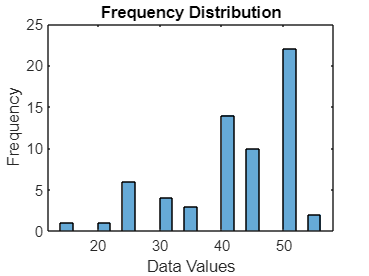


% Plotting the line graph
figure;
histogram(data, 'BinWidth', 2); % Change the 'BinWidth' according to your preference
title('Frequency Distribution');
xlabel('Data Values');
ylabel('Frequency');